# Section 8: Data analysis with tables

## Read in an example dataset

T = readtable('airlinesmall.csv', 'TreatAsMissing', 'NA') %reading the airlinesmall csv dataset and treat 'NA' as missing (in demos folder of your matlab installation)

T = 123523×29 table
    Year    Month    DayofMonth    DayOfWeek    DepTime    CRSDepTime    ArrTime    CRSArrTime    UniqueCarrier    FlightNum    TailNum    ActualElapsedTime    CRSElapsedTime    AirTime    ArrDelay    DepDelay    Origin      Dest      Distance    TaxiIn    TaxiOut    Cancelled    CancellationCode    Diverted    CarrierDelay    WeatherDelay    NASDelay    SecurityDelay    LateAircraftDelay
    ____    _____    __________    _

**Following topics are covered**

- **Data aggregation**

- **Group filtering**

- **Data manipulation**

- **Combining data**

- **Visualization**

## 1. Data aggregation ([https://mathworks.com/help/matlab/ref/double.groupsummary.html](https://mathworks.com/help/matlab/ref/double.groupsummary.html))

groupvars = ["Year", "Month"]; % aggregates values based on "Year" and "Month" column
methods = ["mean", "std"]; % apply mean and std function on datavars
datavars = ["ArrDelay"; "DepDelay"]; % apply methods on "ArrDelay" and "DepDelay" columns
T_agg = groupsummary(T, groupvars, methods, datavars) %getting mean and std from ArrDelay and DepDelay for each month with the groupcount

T_agg = 255×7 table
    Year    Month    GroupCount    mean_ArrDelay    std_ArrDelay    mean_DepDelay    std_DepDelay
    ____    _____    __________    _____________    ____________    _____________    ____________

    1987     10         448           5.8108           16.721          4.5676           13.262   
    1987     11         423           7.5311           20.647          6.1005           16.112   
    1987     12         440            11.97           27.786          10.528           26.607   
    1988      1         436           11.053           22.862          8.1607           17.951   
    1988      2         413           8.2138           24.499          7.7824           21.678   
    1988      3         445           10.014           

## 2. Group filtering ([https://mathworks.com/help/matlab/ref/double.groupfilter.html](https://mathworks.com/help/matlab/ref/double.groupfilter.html))

groupvars = ["Year", "Month"]; % aggregates values based on "Year" and "Month" column
methods = @(x) x == max(x); % apply max on filter as function handle to datavars
datavars = "ArrDelay"; % apply max function on this column
T_filt = groupfilter(T, groupvars, methods, datavars) % filtered by max ArrDelay in each month

T_filt = 255×29 table
    Year    Month    DayofMonth    DayOfWeek    DepTime    CRSDepTime    ArrTime    CRSArrTime    UniqueCarrier    FlightNum    TailNum    ActualElapsedTime    CRSElapsedTime    AirTime    ArrDelay    DepDelay    Origin      Dest      Distance    TaxiIn    TaxiOut    Cancelled    CancellationCode    Diverted    CarrierDelay    WeatherDelay    NASDelay    SecurityDelay    LateAircraftDelay
    ____    _____    __________    

## 3. Data manipulation

T_filt_sorted = sortrows(T_filt, "ArrDelay", "descend"); % sort the table in descending order on Departure Delay column
T_filt_sorted.Date = datetime(T_filt_sorted.Year, T_filt_sorted.Month, T_filt_sorted.DayofMonth); % create a datetime column
T_filt_sorted = movevars(T_filt_sorted,"Date",'Before',"DepTime"); % reorder it and push the Date before the Departure Time column
T_filt_sorted = removevars(T_filt_sorted, ["Year", "Month", "DayofMonth", "DayOfWeek"]) %r emove the date columns

T_filt_sorted = 255×26 table
       Date        DepTime    CRSDepTime    ArrTime    CRSArrTime    UniqueCarrier    FlightNum    TailNum    ActualElapsedTime    CRSElapsedTime    AirTime    ArrDelay    DepDelay    Origin      Dest      Distance    TaxiIn    TaxiOut    Cancelled    CancellationCode    Diverted    CarrierDelay    WeatherDelay    NASDelay    SecurityDelay    LateAircraftDelay
    ___________    _______    __________    _______    __________    ____

## 4. Combining Data ([https://mathworks.com/help/matlab/ref/table.join.html](https://mathworks.com/help/matlab/ref/table.join.html))

T_joined = join(T_filt, T_agg, "Keys", ["Year", "Month"], "RightVariables", "mean_ArrDelay") % joining the aggregated values "mean_ArrDelay" of the right dataset T_agg on the keys "Year" and "Month". Keys must be named the same in both datasets.

T_joined = 255×30 table
    Year    Month    DayofMonth    DayOfWeek    DepTime    CRSDepTime    ArrTime    CRSArrTime    UniqueCarrier    FlightNum    TailNum    ActualElapsedTime    CRSElapsedTime    AirTime    ArrDelay    DepDelay    Origin      Dest      Distance    TaxiIn    TaxiOut    Cancelled    CancellationCode    Diverted    CarrierDelay    WeatherDelay    NASDelay    SecurityDelay    LateAircraftDelay    mean_ArrDelay
    ____    _____    <s

## 5. Visualization ([https://mathworks.com/help/matlab/creating_plots/plots-that-support-tables.html](https://mathworks.com/help/matlab/creating_plots/plots-that-support-tables.html))

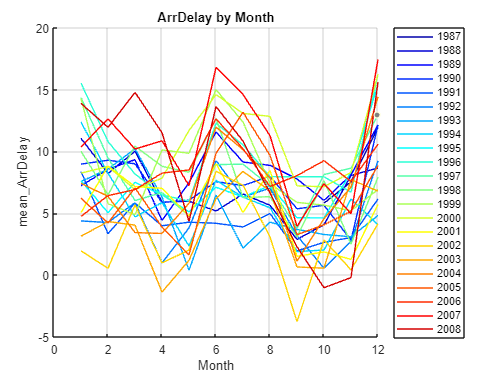

figure;
hold on; grid on;
u_years = unique(T_joined.Year)';
for year = u_years
    T_yearData = T_joined(T_joined.Year == year, :);
    plot(T_yearData, "Month", "mean_ArrDelay");
end
colororder(jet(numel(u_years)))
hold off;
title('ArrDelay by Month');
legend(string(uniqueYears), 'Location', 'eastoutside');